# Passband Up- and Down-Conversion In-Class Exercises

## Up and Down-Conversion in Time-Domain 

In this exercise, we will perform simple up and down-conversion.  Normally, up and down-conversion are performed largely in analog.  But, we will simulate this numerically.  We start with a simple complex baseband time-domain signal:

Create a sampled version of the signal a `u` for `t \in [0,T]` at the sample rate `fs`.  All parameters are below.  Plot the real and imaginary components of `u` vs. t.  Draw the time axis in micro-seconds and label the axis.

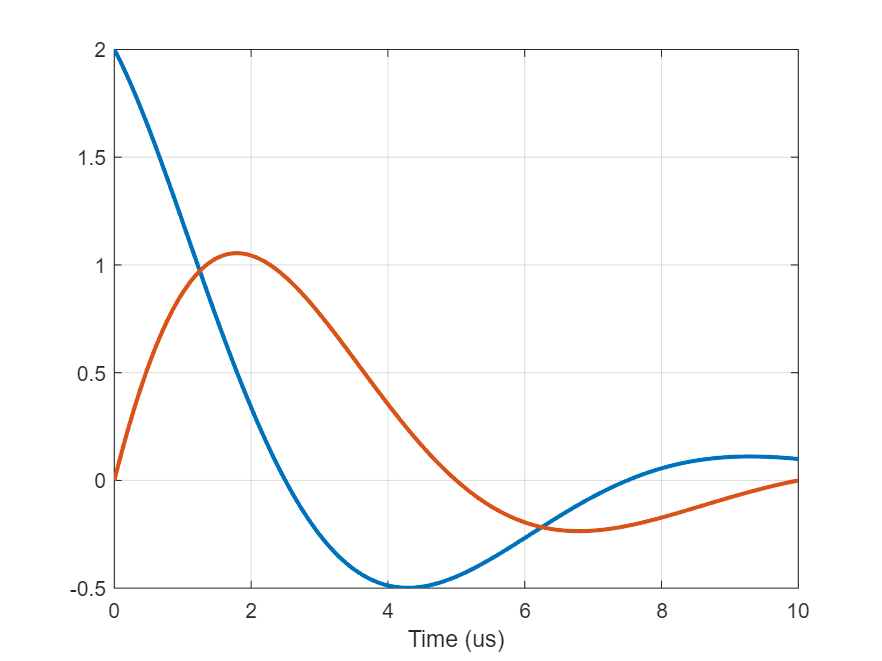

% Constants
T = 1e-5;      % Time period in sec
alpha = 3e5;   % Decay constant in 1/sec
w = 2*pi*1e5;  % Angular freq in rad/sec
fs = 100e6;    % Sample rate in Hz
u0 = 2;

% TODO:  Create sampled time-domain signal
%    t = ...
%    u = ...
%    plot(...)
t = (0:1/fs:T)';
u = u0*exp((1i*w-alpha)*t);
plot(t*1e6, [real(u) imag(u)], 'LineWidth', 2);
grid on;
xlabel('Time (us)');

Now digitally upconvert the signal with the carrier `fc`.  Plot the resulting real passband signal, `u`p.  Also plot the so-called envelope, `uenv = abs(u)`

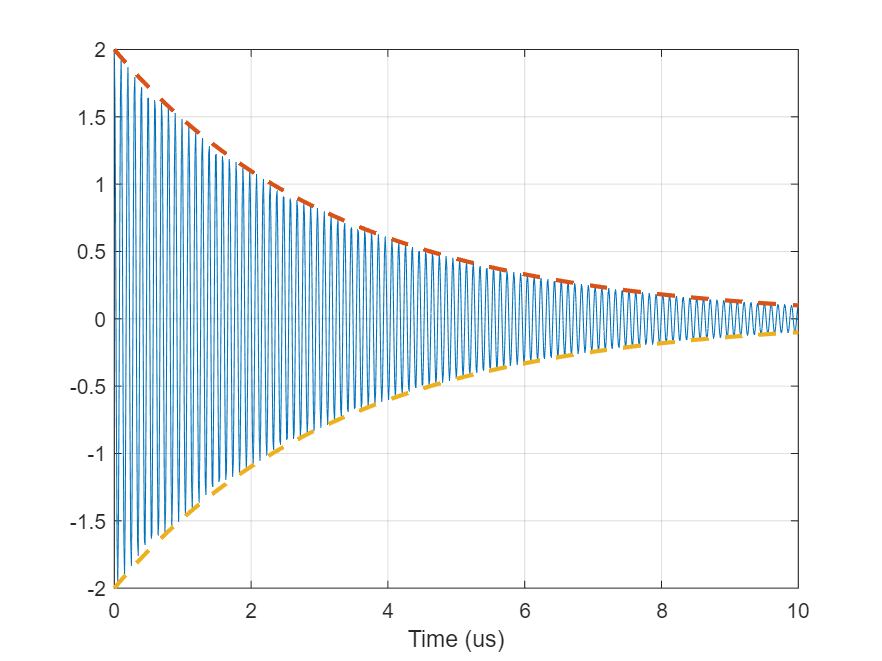

fc = 10e6;  % Carrier in Hz

% TODO:  Create real passband signal
%    up = ...
up = real(u.*exp(2*pi*1i*fc*t));
uenv = abs(u);
plot(t*1e6, up);
hold on;
plot(t*1e6,[uenv -uenv],'--','LineWidth',2);
hold off;
grid on;
xlabel('Time (us)');

For the down-conversion, we will first perform the mixing:  

Compute `v` and plot its real and imaginary components.

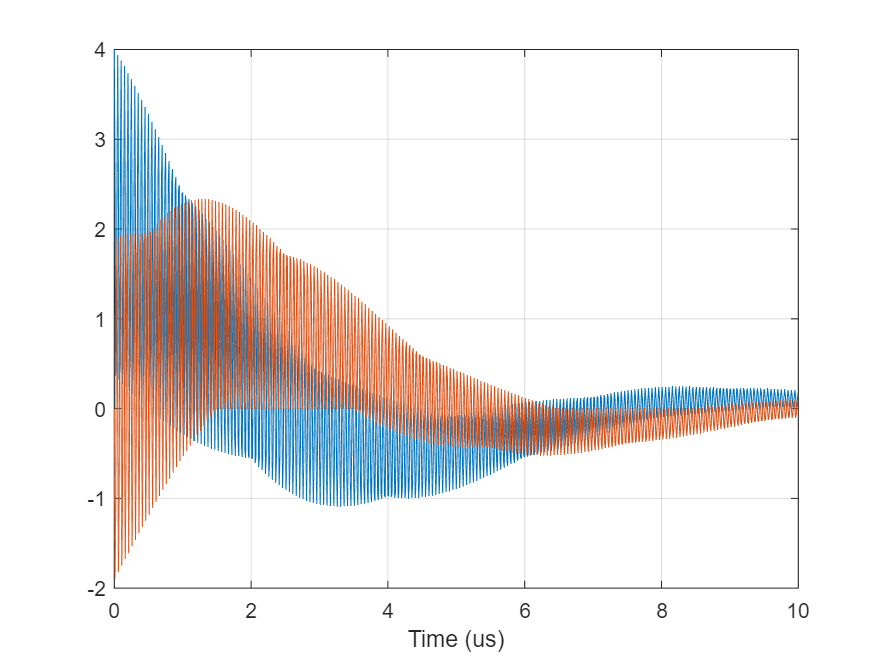

% TODO
%    v = ...
%    plot(...)
v = 2*up.*exp(-2*pi*1i*fc*t);
plot(t*1e6, [real(v) imag(v)]);
grid on;
xlabel('Time (us)');

Finally, to recover the signal we lowpass filter `v`.  MATLAB has a rich set of tools for performing lowpass filtering.  Here, we will use a simple command, `lowpass` .   We will see later that we should select the passband frequency <`fc/2.  `Use this setting for fpass and plot the resulting low-pass signal `r`.  It should be close to the transmitted signal u.  

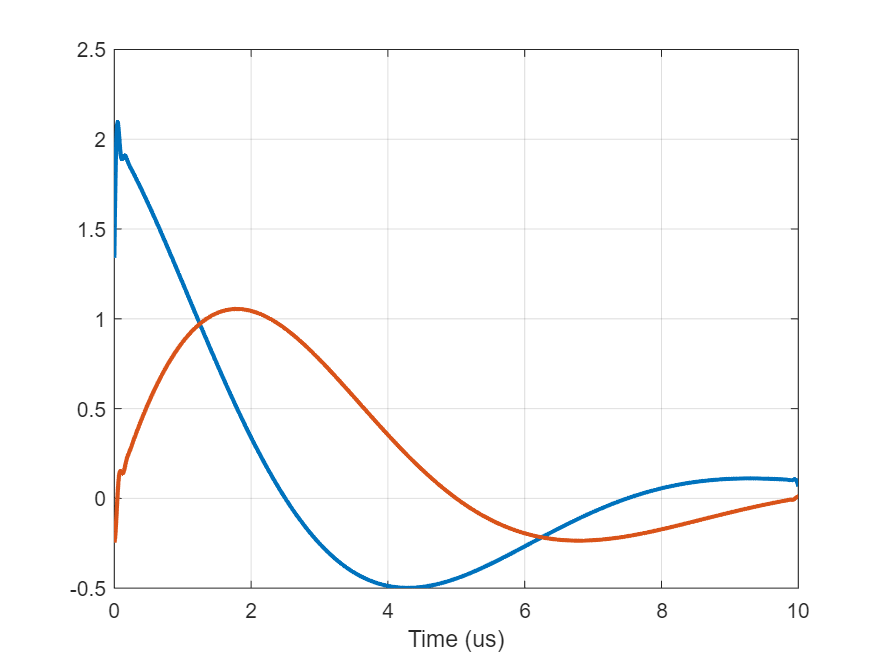

fpass = fc/2;
r = lowpass(v,fpass,fs);
plot(t*1e6, [real(r) imag(r)], 'LineWidth', 2);
grid on;
xlabel('Time (us)');

## Computing a Fourier Transform with an FFT

In this exercise, you will see how to approximately compute the Fourier Transform of a sampled signal with the FFT.  First, we create a sampled-signal.

- Generate random complex symbols, `sym[k]=exp(1i*theta[k])` where `theta[k]` is uniform in `[0,2*pi]` and `k=1,...,nsym`

- Create an up-sampled version of sym, denoted u:  `u[n]=sym[k]` for `n = k*sampPerSym-1,...,(k+1)*sampsPerSym`.  

- Plot the `real(u) vs.` time in micro-seconds.  

`So, u `is a signal that randomly changes phases every `sampsPerSym.`

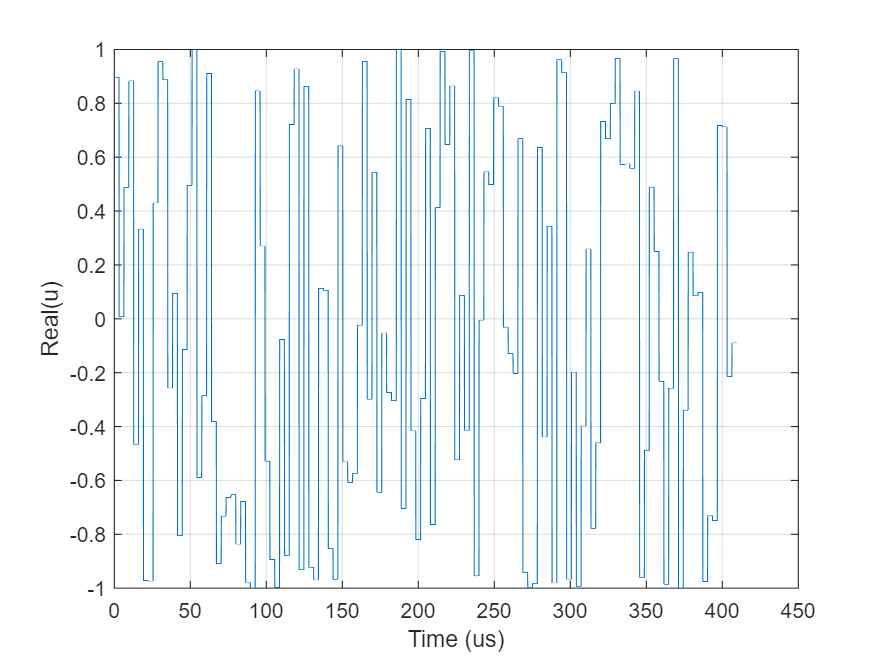

sampPerSym = 2^5;   % number of samples per symbol
nsym = 2^7;         % number of symbols
nsamp = sampPerSym*nsym;  % total number of samples
fs = 10e6;          % sample rate in Hz

% TODO:  Generate nsym random complex symbols 
%   sym = ...
sym = exp(2*pi*1i*rand(nsym,1));

% TODO:  Create up-sampled version of sym
%   u = ...
u = repmat(sym.',sampPerSym,1);
u = u(:);

% TODO:  Plot real(u) vs. time in us
t = (0:nsamp-1)'/fs;
plot(t*1e6, real(u));
xlabel('Time (us)');
grid on;
ylabel('Real(u)');

We will now approximately compute the sampled Fourier Transform of `u`:

- Compute the scaled FFT of `u`:  `U = (1/fs)*ifft(u)`

- Use the command `fftshift `to cyclically rotate the FFT so that the DC component is in the middle.

- Create a vector, `fMHz,` for the frequencies corresponding to `U` in MHz.  Note that `U(k)` is at frequency (`k/nsamp-0.5)*fs` .  The -0.5 term is due to the `fftshift`

- Plot `abs(U)` vs. `fMHz`.  

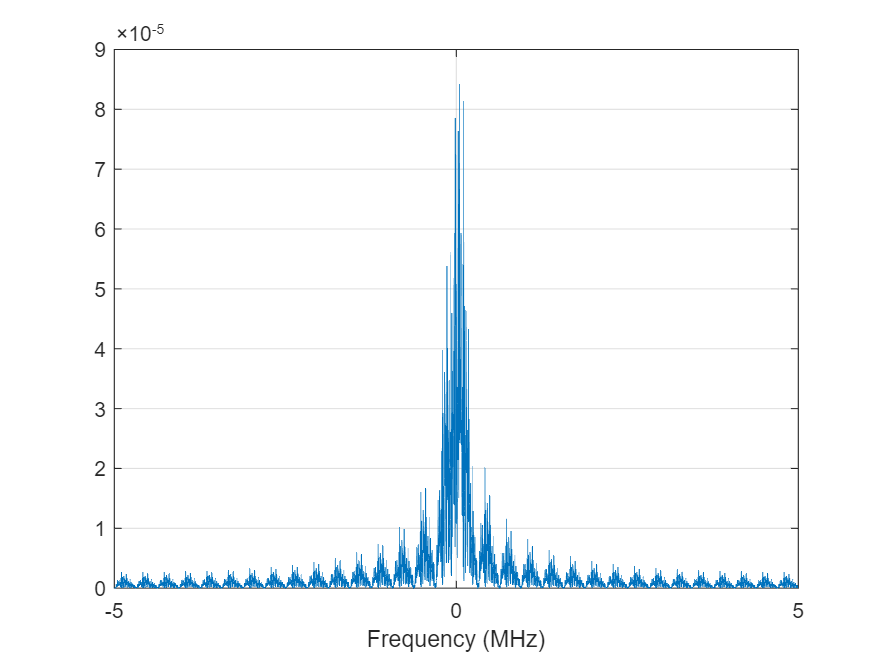

% TODO:
%   U = ...
%   fMHz = ...
%   plot(...)
U = (1/fs)*fft(u);
U = fftshift(U);
fMHz = ((1:nsamp)'/nsamp-0.5)*fs/1e6;
plot(fMHz, abs(U));
grid on; 
xlabel('Frequency (MHz)');

## Visualizing Up-Conversion in Frequency Domain

We will next visualize the up-conversion in frequency domain.  Using the signal `u` from the previous part, create a real-passband signal, `up, `modulated with a carrier of `fc=2 MHz.`

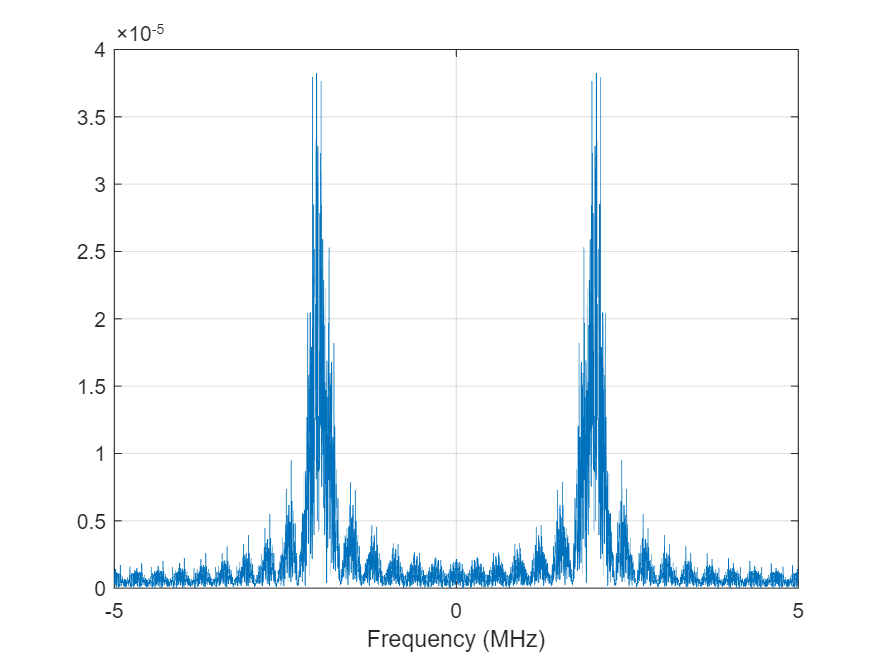

fc = 2e6;  % Carrier frequency MHz

% TODO:  Create real passband signal
%   up = ...
up = real(exp(2*pi*1i*fc*t).*u);


% TODO:  Compute and plot the FT of up
%    Up = ...
Up = fftshift(fft(up))/fs;
plot(fMHz, abs(Up));
grid on; 
xlabel('Frequency (MHz)');

## Computing the Power Spectral Density

MATLAB has excellent tools for computing the PSD.  In this component, we will use these tools to compute and plot the PSD of the complex baseband signal and the real passband signal.  We will plot the signals in dB domain.

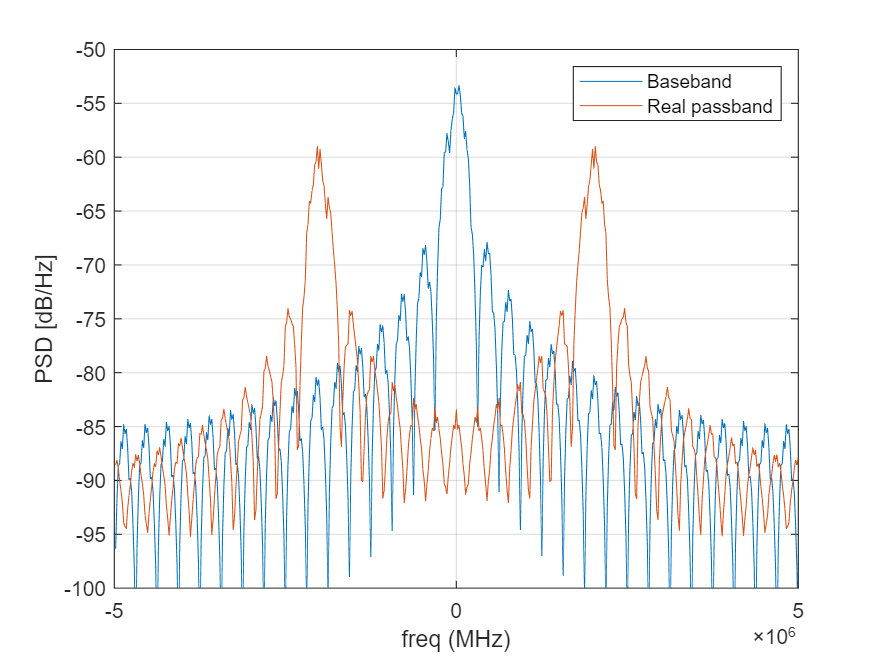

% Run the following command to compute the PSD
[Su, fu] = pwelch(u,hamming(512),[],[],fs,'centered');

% TODO:  Use a similar command to compute the PSD of the real passband
% signal up:
%    [Sup, fup] = pwelch(...)
[Sup, fup] = pwelch(up,hamming(512),[],[],fs,'centered');

% TODO:  Plot the two PSDs in dB / Hz

plot(fu, pow2db(Su));
hold on;
plot(fup, pow2db(Sup));
hold off;
grid on;
ylim([-100,-50]);
legend('Baseband', 'Real passband');
xlabel('freq (MHz)');
ylabel('PSD [dB/Hz]');